# How to create a publication-quality figure using Matlab

## Motivation

As humans are highly visual, good-looking figures may increase the chance that your paper looks good and thus gets accepted by a journal with a higher impact-factor. Here I summarize tips to transform your nothing-but-ordinary figures into publication-quality ones.

## (Before formatting) Preparing a figure

Here we consider a scatter plot with a linear regression line as an example. It looks as follows:

% create an example scatter plot with a linear regression line ------------
clear all;
close all;

% data generation
rng(20180301)

% create a figure
h = figure;
scatter(rand(30, 1), rand(30, 1), 30, 'markerfacecolor', 'r', 'markerfacealpha', 0.4, ...
    'markeredgecolor', 'w', 'markeredgealpha', 0.8)

% formatting axis
xrange = get(gca, 'XLim');
yrange = get(gca, 'YLim');
xlabel('x')
ylabel('y')
title('raw figure')

## General formatting tips

A figure looks typically better when:

- ticks are oriented outside

- box is off

- axis is square

- Fonts are the same across all the labels and texts (Font size of 6 is a nice choice basically for many journals)

- Tick labels at most 3 in each axis

These can be achieved easily as follows:

% ticks orienting outward
set(gca, 'TickDir', 'out')

% box off
set(gca, 'box', 'off')

% square axis
axis square

% same font size (this time 6)
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 6)

% two tick-labels in each axis
set(gca, 'XTick', xrange)
set(gca, 'YTick', yrange)

The figure looks already better. The font size looks too small, but that's fine for now.

## Copy axes 

Typically there are multiple panels in your figure. The way to arrange such spatial relations in a way that you like is copy axes. Essentially you copy your figures and put them in a plain background.

First we define some figure parameters, which can be accepted by many journals.

% figure parameters
figpar.Color =         'w';
figpar.Units =         'centimeters';
figpar.PaperUnits =    'centimeters';

% axis parameters 
axispar.xcolor = 'k';
axispar.ycolor = 'k'; 
axispar.TickDir = 'out';
axispar.TickLength = [0.02 0.02];
axispar.Box = 'off';
axispar.Units = 'centimeters';
axispar.FontName= 'Arial';

% font size & line width for a paper
axispar.FontSize = 6;
axispar.LineWidth = 0.5;

% % use the following setup for making a poster
% axispar.FontSize = 24;
% axispar.LineWidth = 2;

OK, so let's copy our figure into the defined figure.

% define the format of figure
figure(figpar);

% define figure position
figPos = [5 5 10 10]; % this is in cm
set(gcf, 'position', figPos, 'paperposition', figPos);

% offsets in the panels (modifiy along with what you want)
xbegin = 5;
ybegin = 5;
sq = 3;
offset_figlab = 1.5;
figspace_x = 5;
figspace_y = 2;

% new panel position
ax_new = axes(axispar, 'position', [xbegin ybegin sq sq]);

% off axis for the offset axis later
box off
axis off

% copy & paste the figure
ax_old = findobj(h, 'type', 'axes');
copyobj(ax_old.Children, ax_new); delete(h);

% Legend
axes(axispar,'position',[xbegin-offset_figlab ybegin+sq-1 1 1])
axis off
title('A','fontsize',8)

## Introduce offset axis

One final push is to introduce an offset of your x- and y-axis. This is quite a minor change in your figure, but indeed your figure would look better in the end. As you go through the following tidious manipulations on parameters in your figure axes, you can achieve that.

% get the current axes
h = ax_new;

% offset (currently 5%); shift ratio of x- and y-axis (0 - 1)
shift_percentage = [0.05, 0.05];

base_pos = get(h,'position');

expos_1 = base_pos;
expos_1(1) = expos_1(1)-expos_1(3)*shift_percentage(1);
expos_1(3) = 1/10^10;
a1 = axes(axispar,'position', expos_1);
expos_2 = base_pos;
expos_2(2) = expos_2(2) - expos_2(4)*shift_percentage(2);
expos_2(4) = 1/10^10;
a2 = axes(axispar,'Position', expos_2);

set(a2,'xtick',get(h,'xtick'),'xticklabel',get(h,'xticklabel'))
set(a2,'xlim',get(h,'xlim'))
set(a2,'xlabel',get(h,'xlabel'))
set(a2,'ticklength', axispar.TickLength)

set(a1,'ytick',get(h,'ytick'),'yticklabel',get(h,'yticklabel'))
set(a1,'ylim',get(h,'ylim'))
set(a1,'ylabel',get(h,'ylabel'))
set(a1,'ticklength', axispar.TickLength)

Let's just organize appearance of the plot at last.

xlabel(a2, 'x')
ylabel(a1, 'y')
title(ax_new, 'formatted figure')
set(a2, 'XTick', xrange)
set(a1, 'YTick', yrange)

Finally, save the figure!

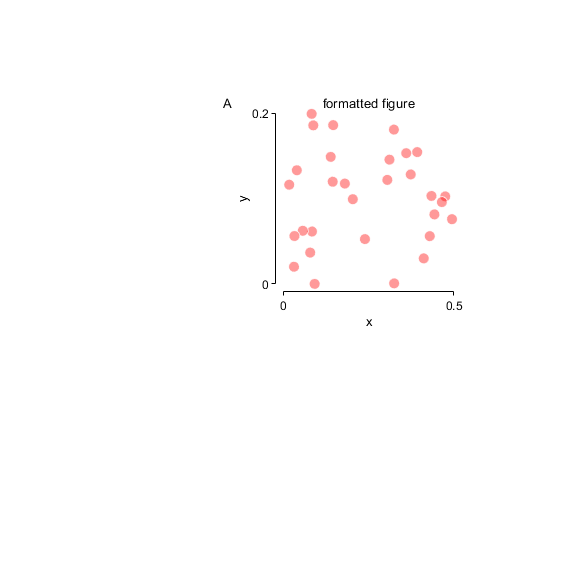

% save
figname = 'your figure path';
savefig([figname '.fig'])
print(gcf,'-dpdf',[figname '.pdf'],sprintf('-r%d',300))

Now you have a vector-map figure at hand, which should be directly used in your paper publication!